This algorithm is our own method, performing the reverse procedure along the Zero rule as depicted in Figure 7 of our paper but allow it to plot the spanning tree in VE procedure. In fact, the algorithm can be more effective with a slight modification, such as copying the dictionary on layer d-1 and pivoting on the copy, resulting in a significant decrease in computing time. If the arrangement is in the form Ax=b, then we denote is by matrix A_=[A|b].

When compared to the standard version, "Symbolic reverse Zero rule," there are no differences except for graph plotting. All detailed function descriptions in this file, excluding graph plotting, can be found there.

Below is an arrangement with 5 lines in R^2.

A_=[-1 0 -1
    0 -1 -1
    1 0 3
    0 1 3
    -1 1 -3]

A_ =     -1     0    -1
     0    -1    -1
     1     0     3
     0     1     3
    -1     1    -3


The following command will first construct a dictionary without any objective function, which may not be primal feasible, and then apply the reverse procedure. 

Additionally, if one needs to compute the coordinates of all vertices, the function "compute(vertex,A_)" provides the coordinates of vertices from the cobasis. All the information in this file is the same as "Symbolic reverse Zero rule" except that it can plot the graph.

tic

[B,N,A]=dictionary_noobj(A_);
[reversezeros,vertex]=reverse(B,N,A);

toc

Elapsed time is 1.252364 seconds.


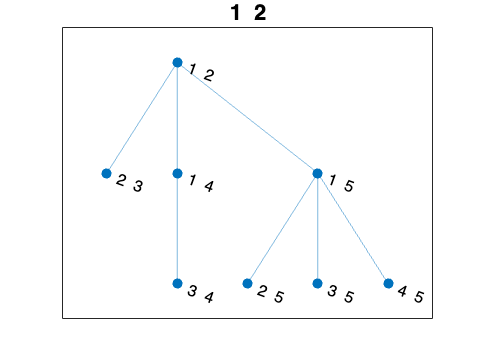


plot(reversezeros,'Layout','layered');
title(num2str(N(2:end)))


result=comput(vertex,A_)

result =      1    -2
     1     1
     1     3
     3     0
     3     1
     3     3
     4     1
     6     3


This function construct the initial dictionary with out objective function from the coefficient matrix of arrangement, output basis B, co-basis N, and coefficient matrix A to repersent the initial dictionary x_B=Ax_N. We use 0 to represent g to make it always the first entery of N.

function [B,N,A]=dictionary_noobj(A_)
[~,d]=size(A_);d=d-1;A_=sym(A_);

A0=A_(:,1:end-1);b=A_(:,end);

A_N=[];N=0;
[n,d]=size(A0);

for i=1:n
    if rank(A0(1:i,:))>rank(A0(1:i-1,:))
        A_N=[A_N;A0(i,:)];
        N=[N,i];
        if rank(A_N)==d
            break
        end 
    end
end

B=[setdiff(1:n,N(2:end))];

A=[b(B(1:end)),zeros(n-d,d)]-A0(B(1:end),:)*inv(A_N)*[b(N(2:end)),-eye(d)];
A=simplify(A);
end

This function is based on the input initial dictionary x_B=Ax_N and performs the reverse along the Zero rule.

The input of "reverse(B,N,A)": 

    B: basis; N: cobasis; A: coefficient matrix;

The output of "reverse(B,N,A,tim_difference,tim_ver)": 

    "vertex": a matrix listing exactly one cobasis for each vertex, the number of rows corresponds to the number of vertices in the arrangement.

    "reversezeros": the information of spanning tree rooted at input N, each node of the spanning tree a cobasis of some dictionary.

function [reversezeros,vertex]=reverse(B,N,A)
s={};t={}; % inaddition to the "Symbolic reverse Zero rule", we use s to record those starting nodes and t to record those ending nodes, and construct the graph before exceed the function.
j=2;i=1;
layer=0;
d=length(N)-1;

vertex=[];
lexmin=lexicography(B,N,A);
if lexmin==1
    vertex=[vertex;N(2:end)];
end

while j<=length(N)+1
    if j<=length(N)
        reversezero=testzeroreserse(B,N,A,i,j);
        if reversezero==1
            s=[s,num2str(N(2:end))]; % let the cobasis before update be the starting node.
            [B,N,A]=pivotrowcolumn(B,N,A,i,j);
            t=[t,num2str(N(2:end))]; % let the cobasis after update be the ending node.
            lexmin=lexicography(B,N,A);
            if lexmin==1
                vertex=[vertex;N(2:end)];
            end
            if layer==d-1 % if the layer before update is d-1, one can skip the study on the updated dictionary.
                [tempi,tempj]=selectzero(B,N,A); % apply the Zero rule and not update position.
                [B,N,A]=pivotrowcolumn(B,N,A,tempi,tempj);
                [i,j]=increment(i,j,B); % After updating, move to the next position and use B to verify if it goes out of the dictionary.
            else
                layer=layer+1; % if the layer before update smaller than d-1, enter the next layer and initialize position.
                i=1;j=2;
            end
        else
            [i,j]=increment(i,j,B);
        end
    else
        [i,j]=selectzero(B,N,A);
        if (isempty(i)==0 && isempty(j)==0)
            Bi=B(i);Nj=N(j);
            [B,N,A]=pivotrowcolumn(B,N,A,i,j);
            layer=layer-1;
            i=find(B==Nj);j=find(N==Bi);
            [i,j]=increment(i,j,B);
        else
            reversezeros=graph(s,t); % based on the relation of staring and ending node, we construct a graph and plot out of the function.
            break
        end
    end
end
end

This function used to do pivot(B(i),N(j)) on the input dictionary x_B=Ax_N and update it, the input consist of all basis B, co-basis N, coefficient matrix A and the i,j-th entry in A, output are corresponding B,N,A for updated dictionary.

function [B,N,A]=pivotrowcolumn(B,N,A,i,j)
C=sym(zeros(size(A)));
for l=1:length(B) %compute remainders in the pivot.
    C(l,:)=A(l,:)-A(i,:)*A(l,j)/A(i,j);
end
C(i,:)=-A(i,:)/A(i,j); % compute the row in the pivot.
C(:,j)=A(:,j)/A(i,j);C(i,j)=1/A(i,j); % compute the column the the fixed entry in pivot.
N0=N;B0=B;
B(i)=N0(j);[B,I]=sort(B); % sort new B.
N(j)=B0(i);[N,J]=sort(N); % sort new N.
C=C(:,J);C=C(I,:);A=simplify(C); % permute the row and column of C in correspondence manner.
end

This function is designed to apply Zero rule on a dictionary x_B=Ax_N and determine the fixed position of this rule as the i,j-th entry. If both i,j empty, the current dictionary is a terminal.

function [i,j]=selectzero(B,N,A)
i=[];j=[];
for j=2:length(A(end,:))
    temp=find(A(find(B<N(j)),j)~=0);
    if isempty(temp)==0
        i=min(temp);
        break
    end
end
end

This function designed to test if the i,j-th entery on dictionary x_B=Ax_N a valid reverse pivot about the Zero rule, if yes, reversezero=1, otherwise =0.

function reversezero=testzeroreserse(B,N,A,i,j)
reversezero=0;% i: the i-th of B, which is s in the prop; j: the j-th of N, which is r in prop
if N(j)<B(i) && A(i,j)~=0
    B0=find(B<N(j));B0(B0==i)=[];
    if all(A(B0,j)==0)
        N0=find(N<B(i));N0(1)=[];N0(N0==j)=[];
        if isempty(N0)==1
            reversezero=1;
        else
            reversezero=1;
            for l=N0
                if all(A(B<N(l),l)==0)==0
                    reversezero=0;
                    break
                else
                    if l>j && A(i,l)~=0
                        reversezero=0;
                        break
                    end 
                end
            end
        end
    end
end
end

This function update [i,j] to the next candidate with a size of dictionary. Kindly noticed that this is different from the no objective function case, since dictionaries in this file has no objective function.

function lexmin=lexicography(B,N,A)
B0=B(find(A(:,1)==0));
lexmin=1;
if isempty(B0)==1
    lexmin=1;
else
    for i=length(B0):-1:1
        N0=find(N(2:end)<B0(i))+1;
        if isempty(N0)==0
            if any(A(find(B==B0(i)),N0)~=0)==1
                lexmin=0;
                break
            end
        else
            break
        end
    end
end

end

This function computes all vertices after enumeration based on the given coefficient matrix of the arrangement and the set of indexes N to obtain coordinate of all vertices in the arranegment.

function result=comput(result_dic,A_)
[ver,~]=size(result_dic);[~,n_]=size(A_);A_=[A_;-eye(n_)];A_=A_(1:end-1,:);
vertex=[];
for i=1:ver
    vert=inv(A_(result_dic(i,:),1:end-1))*A_(result_dic(i,:),end);
    vertex=[vertex;transpose(vert)];
end
result=sortrows(vertex);
end

This function update [i,j] to the next candidate with a size of dictionary. Kindly noticed that this is different from the no objective function case, since dictionaries in this file has no objective function.

function [i,j]=increment(i,j,B)
i=i+1;
if i==length(B)+1 % use B to verify if it goes out of the dictionary, if yes, go next column and the first row.
    i=1;j=j+1;
end
end